# Load Massive Data File

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\');
latestSweep = latestTimeParse(inputPath,'megaSweep');
tic
%Takes about 2 minutes
load(latestSweep)
toc

Elapsed time is 200.874589 seconds.


clear inputPath latestSweep


# Bad Fits List

r2thresh = 0.5;
bfList = badFitList(sweepData,r2thresh);

# Sandbox

Check

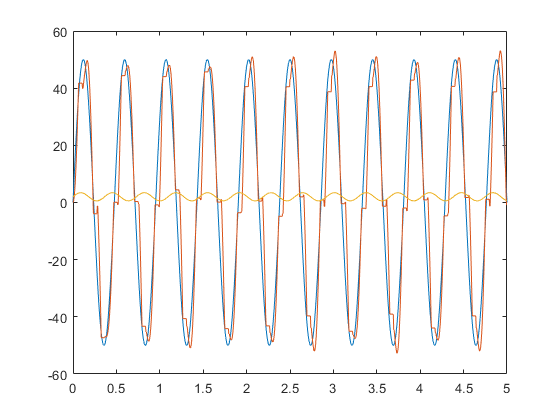

bfIndex = 51000;

sinin = 50*sin(2*pi*bfList(bfIndex,5)*pureSinTime);
hybridOut = sweepData(bfList(bfIndex,2),bfList(bfIndex,4),bfList(bfIndex,6))...
    .hybridInfo(bfList(bfIndex,8)).hybridOut;
hFit = sweepData(bfList(bfIndex,2),bfList(bfIndex,4),bfList(bfIndex,6))...
    .hybridInfo(bfList(bfIndex,8)).hFit;
figure
plot(pureSinTime,sinin,pureSinTime,hybridOut,pureSinTime,hFit)


sweepData(bfList(bfIndex,2),bfList(bfIndex,4),bfList(bfIndex,6))

ans = struct with fields:
            Kp: 161
            Ki: 901
     inputFreq: 2.1000
     smoothOut: [1001×1 double]
         sGain: 1.1957
        sPhase: 0.1293
        sError: 0.2414
    hybridInfo: [1×51 struct]


sweepData(bfList(bfIndex,2),bfList(bfIndex,4),bfList(bfIndex,6)).hybridInfo(bfList(bfIndex,8))

ans = struct with fields:
    switchThresh: 1.4000
       hybridOut: [1×1001 double]
            hFit: [1×1001 double]
           hGain: 0.0037
          hPhase: 0.2943
          hError: 0.9964
         rsquare: 0.0011


rsquare = bfList(bfIndex,9)

rsquare = 0.0011

New Try

%FFT Params
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;   

[newSin,newRSquare] = sineFitMod(hybridOut,pureSinTime,bfList(bfIndex,5),Fs,N,0)

newSin =   -11.9204   -8.9013   -5.8435   -2.7603    0.3350    3.4288    6.5076    9.5582   12.5672   15.5215   18.4082   21.2149   23.9293   26.5395   29.0343   31.4027   33.6346   35.7200   37.6501   39.4164   41.0111   42.4274   43.6592   44.7009   45.5482   46.1973   46.6454   46.8905   46.9317   46.7686   46.4020   45.8336   45.0657   44.1018   42.9460   41.6033   40.0796   38.3815   36.5165   34.4925   32.3185   30.0039   27.5587   24.9936   22.3198   19.5488   16.6928   13.7642   10.7757    7.7403


newRSquare = 0.9566

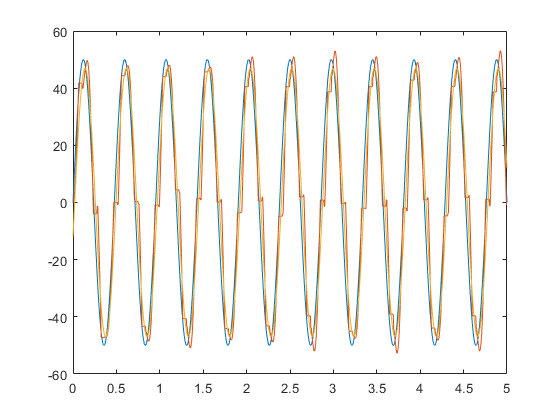


plot(pureSinTime,sinin,pureSinTime,hybridOut,pureSinTime,newSin)


L = length(pureSinTime);
hFFT = fft(hybridOut,N);
P2 = abs(hFFT/L);
P1 = P2(1:L/2+1);

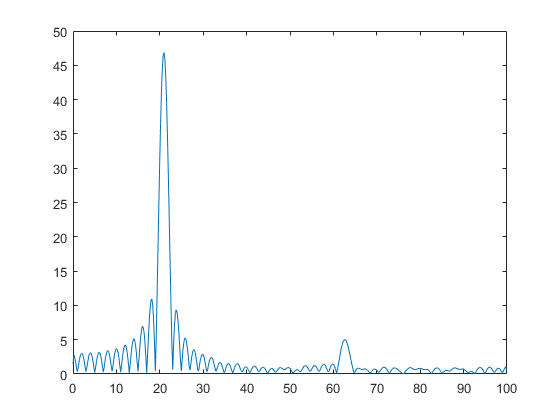

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 